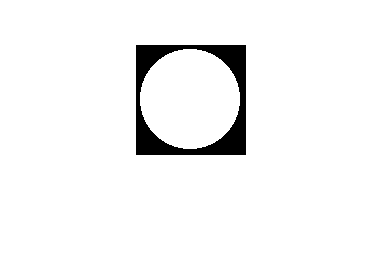

I = circleim(100,5); 
imshow(I)

I

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


tol = 1e-32;
showAns = @(denom) fprintf("1 / %3d = 1 / ( %s )\n", ...
    denom,  frac2bin(denom, tol));

for i = 1:50
   showAns(i);
end

tol = 1e-40;
nRows = 3;
nCols = 200;
arr = zeros(nRows, nCols);
arrSlice = zeros(1,nCols);
test = 0;
for i = 3
    binaryVector = frac2bin2(i, nCols);
    test = max(test, length(binaryVector));
    tempArrSlice = arrSlice;
    for iChar = 1:min(length(binaryVector), nCols)
        tempArrSlice(iChar) = str2double(binaryVector(iChar));
    end
    arr(i,:) = tempArrSlice;
    fprintf("%3d-",i);
    if mod(i,20) == 0
        fprintf("\n");
    end
end
test
imshow(arr)

x = 1254668;
base = sym(4);
xNew = sym(x);
exponentFun = @(x) floor(log(x)/log(base));
exponent = exponentFun(x);
out = zeros(1, eval(exponent));
while xNew > 0
    val = base ^ exponent;
    multiplier = floor(xNew / (val));
    xNew = xNew - (val * multiplier);
    out(exponent + 1) = multiplier;
    exponent = exponentFun(xNew);
end
out = fliplr(out)

out =      1     0     3     0     2     1     1     0     0     3     0


sum = 0;
for i = 1:30
    sum = sum + 3 ^ -i; 
end
sum

sum = 0.5000

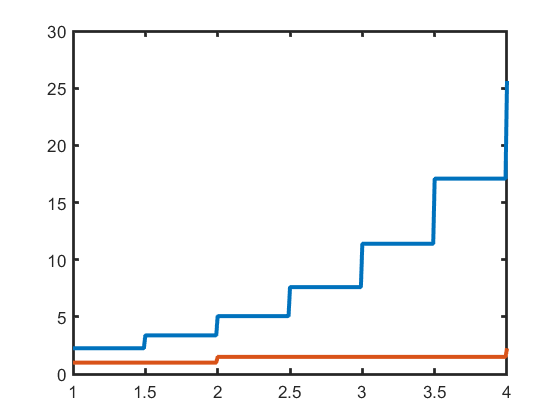

numN = 5;
t = 1:0.01:4;
[f, df] = deal(zeros(numN, length(t)));
clf;
for n = 2
        f(n,:) = 1.* (1 + 1 / n) .^ floor(t * n);
        df(n,:) = (1 + 1 / n) .^ floor(t / n);
        plot(t,f(n,:),t,df(n,:)); hold on;
end

function binaryChar = frac2bin(denom, tol)
    precision = 32;
    tol = vpa(tol, precision); % high precision
    target = vpa(1/denom, precision); % high precision
    val = vpa(0, precision); % high precision
    delta = target - val;
    list = 0;
    listLength = 0;
    exponent = 0;
    while delta > tol
        potentialAdd = 2 ^ exponent;
        if (potentialAdd - delta) < tol
            val = val + potentialAdd;
            delta = target - val;
            if listLength == length(list)
                list =  [list, zeros(1, listLength)];
            end
            listLength = listLength + 1;
            list(listLength) = exponent;
        end
        exponent = exponent - 1;
    end
    list = (-1 * list(1:listLength)) + 1;
    binaryChar = repmat('0',1,list(end));
    binaryChar(list) = '1';
end

function binaryChar = frac2bin2(denom, nBin)
    syms target tol val delta potentialAdd exponent
    precision = ceil(log(2 ^ nBin));
    hp = @(x) vpa(x, precision);
    tol = hp(sym(10) ^ -sym(precision)); % high precision
    target = hp(1/sym(denom)); % high precision
    val = hp(sym(0)); % high precision
    delta = hp(target - val);
    list = 0;
    listLength = 0;
    exponent = hp(0);
    while -exponent < nBin 
        fprintf("************ %s **********", exponent);
        potentialAdd = hp(sym(2) ^ exponent);
        potentialAdd
        if hp(potentialAdd - delta) < tol
            val = hp(val + potentialAdd);
            delta
            delta = hp(delta - potentialAdd);
            delta
            if listLength == length(list)
                list =  [list, zeros(1, listLength)];
            end
            listLength = listLength + 1;
            list(listLength) = exponent;
        end
        exponent = hp(exponent - sym(1));
    end
    list = (-1 * list(1:listLength)) + 1;
    binaryChar = repmat('0',1,list(end));
    binaryChar(list) = '1';
end
